# Parameters


L = 1.200; % Total length of the bridge in meters

num_axles = 6; % Number of axles
P1 = 140;
P= [135/2, 135/2, 135/2, 135/2, 182/2, 182/2]; 
dx = 0.001; % Step size for moving train in meters
num_sections = 1200; % Number of sections along the bridge for calculations
x = linspace(0, L, num_sections); % Discretize the bridge length
total_weight = P(1)+P(2)+P(3)+P(4)+P(5)+P(6) % Total weight of the train in Newtons

total_weight = 452

% Axle positions (in meters)
x_train_spacing = [52, 228, 392, 568, 732, 908] / 1000; % Convert mm to meters
x_train_indices = [52, 228, 392, 568, 732, 908];

% Initialize envelopes
shear_force_max = zeros(num_sections, 1) -100000000; % Maximum shear force envelope
moment_max = zeros(num_sections, 1)-1000000000;      % Maximum bending moment envelope
shear_force = zeros(12, num_sections);
bending_moment = zeros(12, num_sections); 
train_loc = linspace(-50,290, 12);

% Moving train across the bridge
for train_pos = 1:12
    % Calculate axle positions along the bridge for current train position
    sum_Ma=0;
    for axles = 1:6 % Calculate the moment around point A to determine reaction at B
        sum_Ma = sum_Ma + (train_loc(train_pos)+x_train_indices(axles))*P(axles)*0.001;
    end
   % Reaction at B using moment equilibrium equation
    By = sum_Ma / L % Reaction at B (right support)
    % Sum of vertical forces for equilibrium to find Ay
    sum_Fy = total_weight; % Sum of all downward forces (total weight of train)
    Ay = sum_Fy - By % Reaction at A (left support)
    
    % Calculate shear force and bending moment at each section
    shear_force(train_pos, 1:train_loc(train_pos)+x_train_indices(1)) = Ay;
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(1):train_loc(train_pos)+x_train_indices(2)) = Ay-P(1);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(2):train_loc(train_pos)+x_train_indices(3)) = Ay-P(1) -P(2);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(3):train_loc(train_pos)+x_train_indices(4)) = Ay-P(1)-P(2)-P(3);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(4):train_loc(train_pos)+x_train_indices(5)) = Ay-P(1)-P(2)-P(3)-P(4);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(5):train_loc(train_pos)+x_train_indices(6)) = Ay-P(1)-P(2)-P(3)-P(4)-P(5);
    shear_force(train_pos, train_loc(train_pos)+x_train_indices(6):1199) = Ay-P(1)-P(2)-P(3)-P(4)-P(5)-P(6);
    shear_force(train_pos,1200)=Ay-P(1)-P(2)-P(3)-P(4)-P(5)-P(6)+ By;
    

    %shear_force()
    
    for i = 1:1200
        bending_moment(train_pos, i) = trapz(shear_force(train_pos, 1:i))*0.001;
    end
    
    % bending_moment(1)=0;
    % bending_moment(2:train_loc(train_pos)+x_train_indices(1))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(1):train_loc(train_pos)+x_train_indices(2))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(2):train_loc(train_pos)+x_train_indices(3))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001+(Ay-2*P)*(train_loc(train_pos)+x_train_indices(3))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(3):train_loc(train_pos)+x_train_indices(4))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001+(Ay-2*P)*(train_loc(train_pos)+x_train_indices(3))*0.001+(Ay-3*P)*(train_loc(train_pos)+x_train_indices(4))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(4):train_loc(train_pos)+x_train_indices(5))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001+(Ay-2*P)*(train_loc(train_pos)+x_train_indices(3))*0.001+(Ay-3*P)*(train_loc(train_pos)+x_train_indices(4))*0.001+(Ay-4*P)*(train_loc(train_pos)+x_train_indices(5))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(5):train_loc(train_pos)+x_train_indices(6))= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001+(Ay-2*P)*(train_loc(train_pos)+x_train_indices(3))*0.001+(Ay-3*P)*(train_loc(train_pos)+x_train_indices(4))*0.001+(Ay-4*P)*(train_loc(train_pos)+x_train_indices(5))*0.001 + (Ay-5*P)*(train_loc(train_pos)+x_train_indices(6))*0.001;
    % bending_moment(train_loc(train_pos)+x_train_indices(6):1199)= (Ay)*(train_loc(train_pos)+x_train_indices(1))*0.001+ (Ay-P)*(train_loc(train_pos)+x_train_indices(2))*0.001+(Ay-2*P)*(train_loc(train_pos)+x_train_indices(3))*0.001+(Ay-3*P)*(train_loc(train_pos)+x_train_indices(4))*0.001+(Ay-4*P)*(train_loc(train_pos)+x_train_indices(5))*0.001 + (Ay-5*P)*(train_loc(train_pos)+x_train_indices(6))*0.001+(Ay-6*P)*(1.2-(train_loc(train_pos)+x_train_indices(6))*0.001);
    % bending_moment(1200)=Ay-6*P+ By;

   
    for i = 1:1200
        % Update envelopes if current values exceed stored max/min values
        if abs(shear_force(train_pos, i))>shear_force_max(i) 
            shear_force_max(i) = shear_force(train_pos, i);
        end
        if bending_moment(train_pos, i)>moment_max(i) 
            moment_max(i)=bending_moment(train_pos, i);
        end
    end
    
end

By = 175.2833

Ay = 276.7167

By = 186.9258

Ay = 265.0742

By = 198.5682

Ay = 253.4318

By = 210.2106

Ay = 241.7894

By = 221.8530

Ay = 230.1470

By = 233.4955

Ay = 218.5045

By = 245.1379

Ay = 206.8621

By = 256.7803

Ay = 195.2197

By = 268.4227

Ay = 183.5773

By = 280.0652

Ay = 171.9348

By = 291.7076

Ay = 160.2924

By = 303.3500

Ay = 148.6500


shear1 = shear_force(1, 1:1200);
shear2=shear_force(2, 1:1200);
shear3=shear_force(3, 1:1200);
shear4=shear_force(4, 1:1200);
shear5=shear_force(5, 1:1200);
shear6 = shear_force(6, 1:1200);
shear7=shear_force(7, 1:1200);
shear8=shear_force(8, 1:1200);
shear9=shear_force(9, 1:1200);
shear10=shear_force(10, 1:1200);
shear11=shear_force(11, 1:1200);
shear12=shear_force(12, 1:1200);


bending1 = bending_moment(1, 1:1200);
bending2 = bending_moment(2, 1:1200);
bending3 = bending_moment(3, 1:1200);
bending4 = bending_moment(4, 1:1200);
bending5=bending_moment(5, 1:1200);
bending6 = bending_moment(6, 1:1200);
bending7=bending_moment(7, 1:1200);
bending8=bending_moment(8, 1:1200);
bending9=bending_moment(9, 1:1200);
bending10=bending_moment(10, 1:1200);
bending11=bending_moment(11, 1:1200);
bending12=bending_moment(12, 1:1200);

max(abs(shear12))

ans = 303.3500

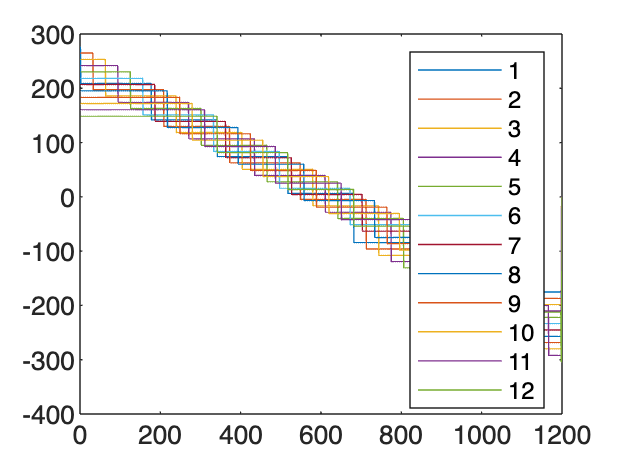

figure;
plot(shear1)
hold on;
plot(shear2) 
hold on;
plot(shear3)
hold on;
plot(shear4)
hold on;
plot(shear5)
hold on;
plot(shear6)
hold on;
plot(shear7)
hold on;
plot(shear8) 
hold on;
plot(shear9)
hold on;
plot(shear10)
hold on;
plot(shear11)
hold on;
plot(shear12)
hold on;
legend("1", "2", "3", "4", "5", "6", "7", "8", "9", "10", "11", "12")

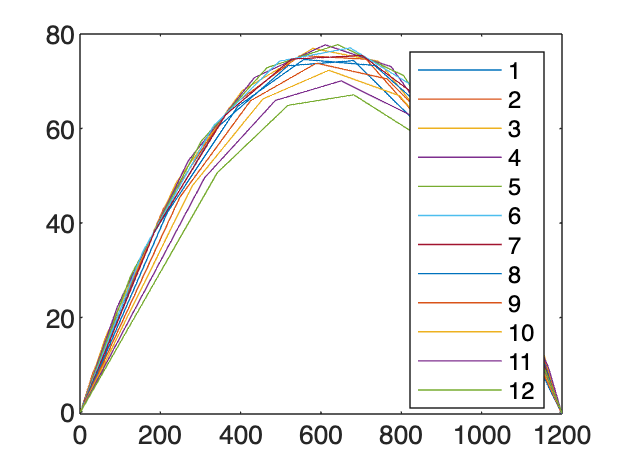


figure;
plot(bending1)
hold on;
plot(bending2)
hold on;
plot(bending3)
hold on;
plot(bending4)
hold on;
plot(bending5)
hold on;
plot(bending6)
hold on;
plot(bending7)
hold on;
plot(bending8)
hold on;
plot(bending9)
hold on;
plot(bending10)
hold on;
plot(bending11)
hold on;
plot(bending12)
legend("1", "2", "3", "4", "5", "6", "7", "8", "9", "10", "11", "12")

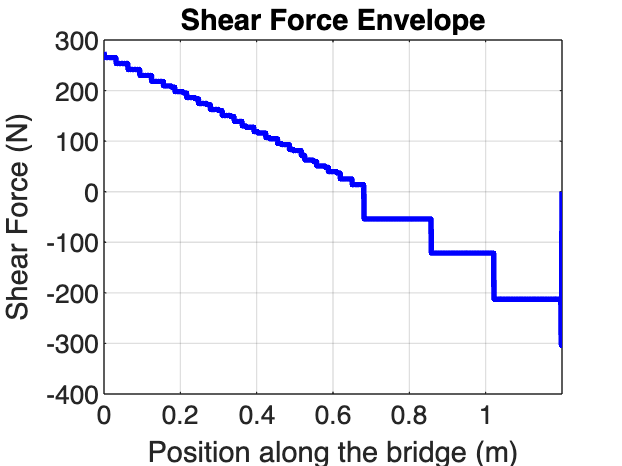

%%add the 8 other bmds

% Plotting the shear force envelope
figure;
plot(x, shear_force_max, 'b-', 'LineWidth', 2);
title('Shear Force Envelope');
xlabel('Position along the bridge (m)');
ylabel('Shear Force (N)');
grid on;
hold off;

max(moment_max)

ans = 77.7353

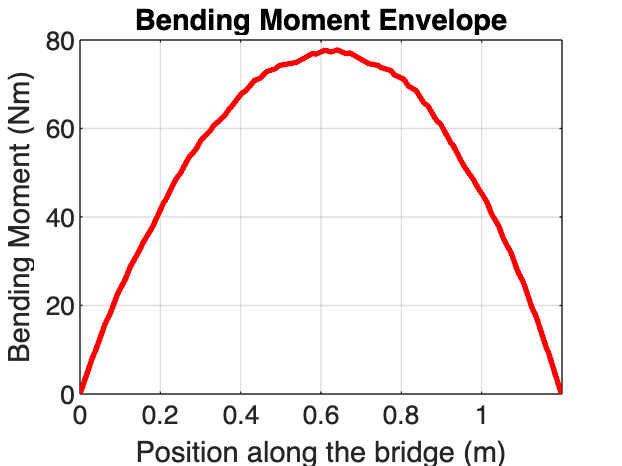

% Plotting the bending moment envelope
figure;
plot(x, moment_max, 'r-', 'LineWidth', 2);
title('Bending Moment Envelope');
xlabel('Position along the bridge (m)');
ylabel('Bending Moment (Nm)');
grid on;
hold off;

## 3. Calculate Sectional Properties

flange = 110;
thick=1.27;
height=60-1.27;
gluetab=5;
gluetab_w=75;
A1 = flange*thick;
y1bot = (height+thick/2);
A2= (gluetab+thick)*thick;
y2bot = (height-thick/2);
A3=A2;
y3bot = y2bot;
A4=thick*(height-2*thick);
y4bot = (height/2);
A5=A4;
y5bot=y4bot;
A6 = gluetab_w*2*thick;%changed to 2xthick
y6bot = 2*thick/2; %changed to 2xthick



ybar = (A1*y1bot + A2*y2bot + A3*y3bot + 2*A4*y4bot+2*A5*y5bot + A6*y6bot)/(A1+A2+A3+A4+A5+A6)% ybar. location of centroidal axis from the bottom, changed I to 2*A4 and 2*a5

ybar = 36.4991

ybot = ybar;
ytop = height + thick-ybar;
% I
y1=abs(ybar-y1bot);
y2=abs(ybar-y2bot);
y3=abs(ybar-y3bot);
y4=abs(ybar-y4bot);
y5=abs(ybar-y5bot);
y6=abs(ybar-y6bot);
I1=flange*thick^3/12;
I2=(gluetab_w+thick)*thick^3/12;
I3=I2;
I4=thick*(height-2*thick)^3/12;
I5=I4;
I6=gluetab_w*(2*thick)^3/12; %changed
IC =A1*y1^2+A2*y2^2+A3*y3^2+2*A4*y4^2+2*A5*y5^2+A6*y6^2 + I1+I2+I3+I4+I5+I6%changed to 2A4, 2A5

IC = 3.6912e+05


% Q at centroidal axes
QAcent = (A6+2*thick*2*(ybar-thick));%2* the last thing
dcent = ybar - (A6*2*thick/2 + 2*2*thick*(ybar-1.27)*(ybar-thick)/2)/(A6+2*2*thick*(ybar-thick)); %%changed to 2xthick
Qcent = QAcent*dcent

Qcent = 1.0091e+04

% Q at glue location
QAglue = flange*thick;
dglue = ytop-thick/2;
Qglue =QAglue *dglue

Qglue = 3.1944e+03


%% 5. Material and Thin Plate Buckling Capacities
E = 4000;
mu = 0.2;
height_total=height+thick;
a=200;
T_max = 4;
T_gmax = 2;
b=gluetab_w;
S_buck1a = (4*pi^2*E)*(2*thick/b)^2/(12*(1-mu^2))*thick*2

S_buck1a = 39.9343

S_buck1b = (4*pi^2*E)*(thick/5)^2/(12*(1-mu^2)) %for new one

S_buck1b = 884.3714

min(S_buck1a, S_buck1b)

ans = 39.9343

S_buck2 =(0.425*pi^2*E)*(thick/((flange-gluetab_w)/2))^2/(12*(1-mu^2))

S_buck2 = 7.6706

S_buck3 = (6*pi^2*E)*(thick/(ytop-thick))^2/(12*(1-mu^2))

S_buck3 = 67.1046

T_buck =(5*pi^2*E)*((thick/a)^2+(thick/(height-2*thick))^2)/(12*(1-mu^2))

T_buck = 9.4441



Sigma_tens = (max(moment_max)*1000)*ybot/I

Unrecognized function or variable 'I'.

Sigma_comp = (max(moment_max)*1000)*ytop/I
Shear_cent= (max(shear_force_max))*Qcent/(I*2*thick)
Shear_glue= (max(shear_force_max))*Qglue/(I*2*gluetab)

%P_vals = [S_top, S_bot, T_cent, T_glue, S_buck1, S_buck2, S_buck3, T_buck]
%CAN CHANGE:
% glue tab distance
%distance between glue tabs
%height of flanges
%% 6. FOS
FOS_tens = 30/Sigma_tens;
FOS_comp = 6/Sigma_comp;
FOS_shear = 4/Shear_cent;
FOS_glue = 2/Shear_glue;
FOS_buck1 = 1/(Sigma_comp/min(S_buck1a, S_buck1b));
FOS_buck2= 1/(Sigma_comp/S_buck2);
FOS_buck3 = 1/(Sigma_comp/S_buck3);
FOS_buckV = 1/(Shear_cent/T_buck);
All_FOS = [FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV];
%% 7. MIN FOS AND FAILURE LOAD PFAIL
min_FOS = min(All_FOS);
All_FOS


%%1. cross section 2
gluetab_w1=80;
A1 = flange*thick;
y1bot = (height+thick/2);
A2= (gluetab+thick)*thick;
y2bot = (height-thick/2);
A3=A2;
y3bot = y2bot;
A4=thick*(height-2*thick);
y4bot = (height/2);
A5=A4;
y5bot=y4bot;
A6 = gluetab_w*thick;
y6bot = thick/2;
ybar = (A1*y1bot + A2*y2bot + A3*y3bot + A4*y4bot+A5*y5bot + A6*y6bot)/(A1+A2+A3+A4+A5+A6);% ybar. location of centroidal axis from the bottom
ybot = ybar;
ytop = height + thick-ybar;
% I
y1=abs(ybar-y1bot);
y2=abs(ybar-y2bot);
y3=abs(ybar-y3bot);
y4=abs(ybar-y4bot);
y5=abs(ybar-y5bot);
y6=abs(ybar-y6bot);
I1=flange*thick^3/12;
I2=(gluetab_w+thick)*thick^3/12;
I3=I2;
I4=thick*(height-2*thick)^3/12;
I5=I4;
I6=gluetab_w*thick^3/12;
I =A1*y1^2+A2*y2^2+A3*y3^2+A4*y4^2+A5*y5^2+A6*y6^2 + I1+I2+I3+I4+I5+I6;
% Q at centroidal axes
QAcent = (A6+thick*2*(ybar-thick));
dcent = ybar - (A6*thick/2 + 2*thick*(ybar-1.27)*(ybar-thick)/2)/(A6+2*thick*(ybar-thick));
Qcent = QAcent*dcent
% Q at glue location
QAglue = flange*thick;
dglue = ytop-thick/2;
Qglue =QAglue *dglue

%% 5. Material and Thin Plate Buckling Capacities
b1=gluetab_w1;
S_buck1 = (4*pi^2*E)*(thick/b1)^2/(12*(1-mu^2))
S_buck2 =(0.425*pi^2*E)*(thick/((flange-b1)/2))^2/(12*(1-mu^2))
S_buck3 = (6*pi^2*E)*(thick/(ytop-thick))^2/(12*(1-mu^2))
T_buck1 =(5*pi^2*E)*((thick/a)^2+(thick/(height-2*thick))^2)/(12*(1-mu^2))
T_buck2 = (5*pi^2*E)*((thick/5)^2+(thick/(height-2*thick))^2)/(12*(1-mu^2))

Sigma_tens = (moment_max(200)*1000)*ybot/I
Sigma_comp = (moment_max(200)*1000)*ytop/I
Shear_cent= (abs(shear_force_max(200)))*Qcent/(I*2*thick)
Shear_glue= abs(shear_force_max(200))*Qglue/(I*2*gluetab)
FOS_tens = 30/Sigma_tens;
FOS_comp = 6/Sigma_comp;
FOS_shear = 4/Shear_cent;
FOS_glue = 2/Shear_glue;
FOS_buck1 = 1/(Sigma_comp/min(S_buck1a, S_buck1b));
FOS_buck2= 1/(Sigma_comp/S_buck2);
FOS_buck3 = 1/(Sigma_comp/S_buck3);
FOS_buckV = 1/(Shear_cent/min(T_buck1, T_buck2));
All_FOS = [FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV];
%% 7. MIN FOS AND FAILURE LOAD PFAIL
min_FOS = min(All_FOS);
All_FOS